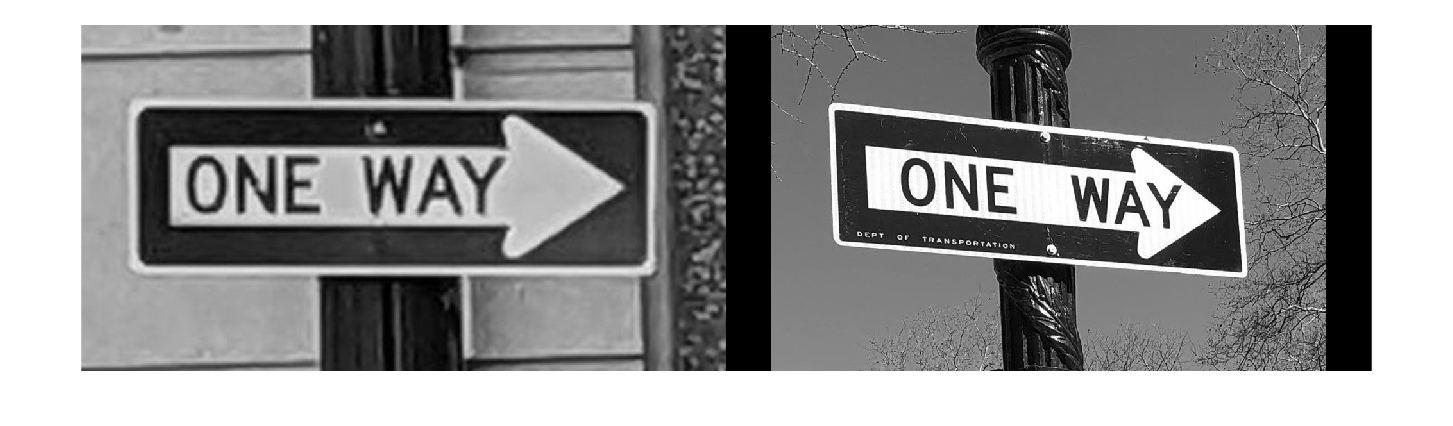

I1 = imread("oneway1.png");
I2 = imread("oneway2.png");

montage({I1,  I2})

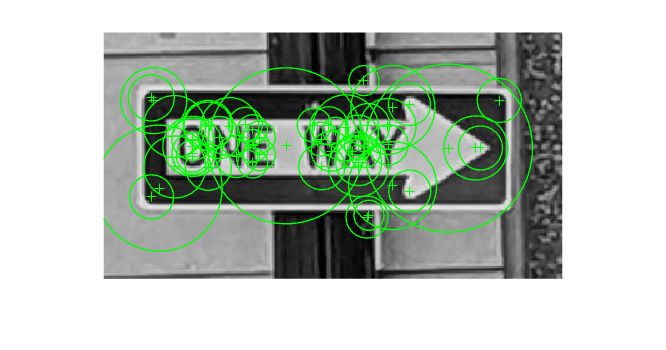

points1 = detectSURFFeatures(I1);
points2 = detectSURFFeatures(I2);

points1 = selectStrongest(points1, 50);
points2 = selectStrongest(points2, 50);

imshow(I1)
hold on
plot(points1)
hold off

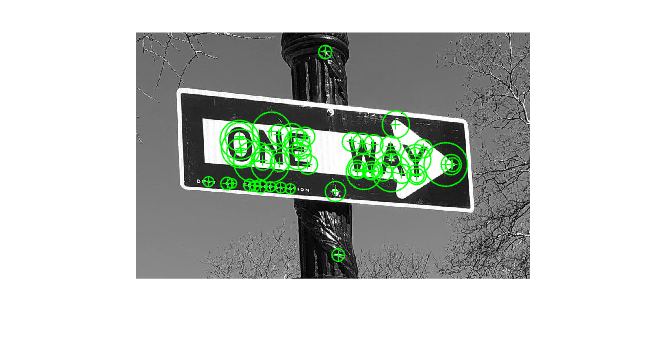


imshow(I2)
hold on 
plot(points2)
hold off


clf

[features1, validPoints1] = extractFeatures(I1, points1);
[features2, validPoints2] = extractFeatures(I2, points2);

indexPairs = matchFeatures(features1, features2)

indexPairs = 6×2 uint32 matrix
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5


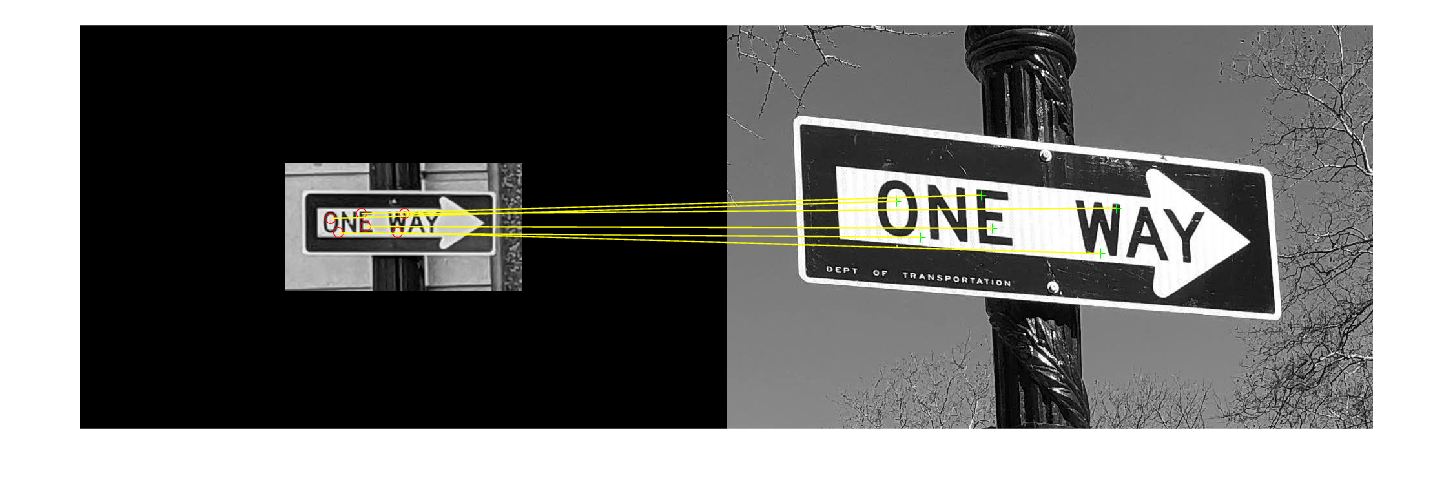

% It is an matching feature numbers, first column is for image 1 image
% feature descriptors and same for second column

matchedPoints1 = validPoints1(indexPairs(:, 1));
matchedPoints2 = validPoints2(indexPairs(:, 2));

showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, "montage")